# Quantitative Methods for Finance

2025 Marina Dolfin

# **QMF2_1_Modelling_Optimization**

## **Optimal asset allocation within the mean-variance portfolio **

**(A short theoretical background is provided at the end of the Live Script.)**

You have a budget of £150,000 to invest. Select 10 companies based on their risk profile: 

- **Low risk:**     Large-cap, stable companies with low volatility (e.g., utilities, consumer goods).

- **Medium risk:**     Mid-cap companies with moderate growth potential (e.g., technology, healthcare).

- **High risk:**     Small-cap or high-growth companies with high volatility (e.g., startups, biotech).

Use historical stock price data to evaluate the volatility and risk of each selected company. Ensure diversification across different sectors to balance the portfolio.

In addition to the selected companies, obtain data for:

- **3-month Treasury Bill:**     Used as a proxy for the risk-free rate.

-  **S&P 500 Index:**     Used as a proxy for the market portfolio to compare the performance of the optimized portfolio.

Find the asset allocation for the optimal portfolio, i.e., efficient and maximizing the Sharpe Ratio, within the mean-variance Markowitz approach. 

**Use daily adjusted closing data on prices for a time window that you choose.**

Determine the risk and gross return (excluding transaction costs) for the optimal portfolio. Additionally, compute 10 efficient portfolios and plot the efficient frontier, comparing it with the Sharpe ratio profile.

Find the budget allocation for all efficient portfolios and the number of shares for the optimal portfolio. 

- **Sector diversity**: Covers tech, finance, energy, healthcare, consumer staples, materials, and discretionary.

- **Geographic diversity**: Includes companies from North America, Europe, Asia, and Australia.

- **Currency exposure**:  FX effects and international diversification benefits.

- **Different risk-return profiles**: From stable dividend-payers (e.g. Nestlé, Unilever) to growth-oriented (Apple, Toyota).

The selected assets consist of large-cap international companies diversified across sectors and regions. Consumer staples stocks are used as low-risk assets, technology and healthcare firms as medium-risk assets, and energy, materials, and cyclical industrial stocks as higher-risk assets. This structure ensures diversification while allowing meaningful differences in volatility and expected return, making the sample suitable for mean–variance portfolio optimization.

clear; close all;

startDate = datetime(2024,1,1,'TimeZone','UTC');
endDate   = datetime(2025,12,31,'TimeZone','UTC');

symbols = {'AAPL','JPM','XOM','PFE','PG','NVS','NSRGY','TM','BHP','UL'};
TTcell = cell(numel(symbols),1);

for i = 1:numel(symbols)
    sym = symbols{i};
    TT  = getYahooDaily(sym, startDate, endDate);

    TT.Properties.VariableNames = string(sym);  % rename column to ticker
    TTcell{i} = TT;
end

TTall = TTcell{1};
for i = 2:numel(TTcell)
    TTall = synchronize(TTall, TTcell{i}, "intersection");
end

% -- Integrity checks ---
TTall = sortrows(TTall);  

if numel(unique(TTall.Time)) ~= height(TTall)
    error("Duplicate dates detected after merging.");
end

if any(ismissing(TTall), "all")
    error("Missing values (NaNs) remain after merging.");
end
% ---------------------------------------------

prices = TTall.Variables;
dates  = TTall.Time;


% Display the first few rows
disp('Adjusted Closing Prices (First 10 Rows):');

Adjusted Closing Prices (First 10 Rows):


disp(head(TTall, 10));

            Time             AAPL      JPM       XOM       PFE        PG       NVS      NSRGY       TM       BHP        UL  
    ____________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    02-Jan-2024 14:30:00     183.9    164.58    95.479    26.127    141.39    93.829    108.23    173.36    63.143     51.06
    03-Jan-2024 14:30:00    182.53    163.87    96.282    26.127    140.54    97.378    109.25    173.53    62.464    51.218
    04-Jan-2024 14:30:00    180.21    164.95    95.442    25.565    141.31


% Write the combined data to an Excel file
writetimetable(TTall, 'AdjustedClosingPrices.xlsx');


**Return construction**

Continuously compounded (log) returns are used, as they are time-additive and standard in mean–variance portfolio optimization. For daily data, the difference with simple returns is negligible.

 rets = tick2ret(prices);
 retDates = dates(2:end);

 

** Risk-free rate **

The risk-free rate is proxied by the 3-month Treasury Bill yield, which is quoted as an annualized rate. To ensure consistency with daily asset returns, the yield is converted to a daily rate using a simple approximation by dividing by 252. This daily risk-free rate is then used in the computation of excess returns and the Sharpe ratio.

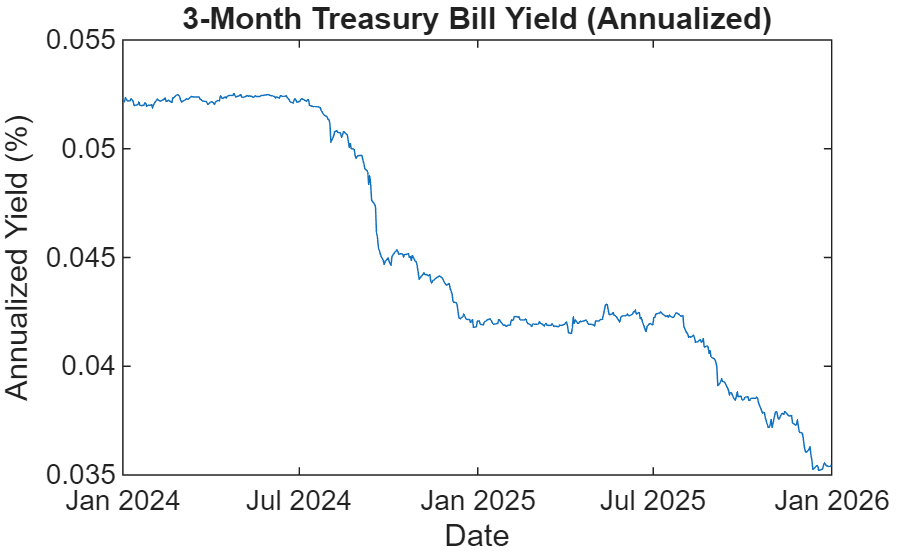

Risk_free_rate = getYahooDaily("^IRX", startDate, endDate);

rf_ann = Risk_free_rate.AdjClose / 100;   % convert % → decimal
rf_daily = rf_ann / 252;                  % simple daily approximation

rf_daily = rf_daily(2:end);


plot(dates, rf_ann)
ylabel('Annualized Yield (%)');
title('3-Month Treasury Bill Yield (Annualized)')
xlabel('Date');

rf = mean(rf_daily, 'omitnan');




#### Benchmark (proxied by SP500)

SP = getYahooDaily("^GSPC", startDate, endDate);

% Align with asset dates
SP = synchronize(TTall(:,1), SP, "intersection");
SP_prices = SP.AdjClose;

SP_rets = diff(log(SP_prices));

mu_SP    = mean(SP_rets);
sigma_SP = std(SP_rets);

fprintf("S&P 500 mean daily return: %.4f\n", mu_SP);

S&P 500 mean daily return: 0.0007


fprintf("S&P 500 daily volatility: %.4f\n", sigma_SP);

S&P 500 daily volatility: 0.0100



corr_SP = corr(rets, SP_rets)

corr_SP =     0.6797
    0.6187
    0.3126
    0.2638
    0.0963
    0.1805
    0.0262
    0.4990
    0.5065
    0.0761



tickers = string(TTall.Properties.VariableNames(:));  
corr_SP = corr_SP(:);                                
corrTbl = table(tickers, corr_SP, ...
    'VariableNames', {'Ticker','CorrWithSP500'});


disp(corrTbl);

    Ticker     CorrWithSP500
    _______    _____________

    "AAPL"        0.67969   
    "JPM"         0.61866   
    "XOM"         0.31263   
    "PFE"          0.2638   
    "PG"         0.096266   
    "NVS"          0.1805   
    "NSRGY"      0.026175   
    "TM"          0.49904   
    "BHP"         0.50654   
    "UL"         0.076099   



## Pre-optimization data analysis checklist

**Price-level sanity checks**

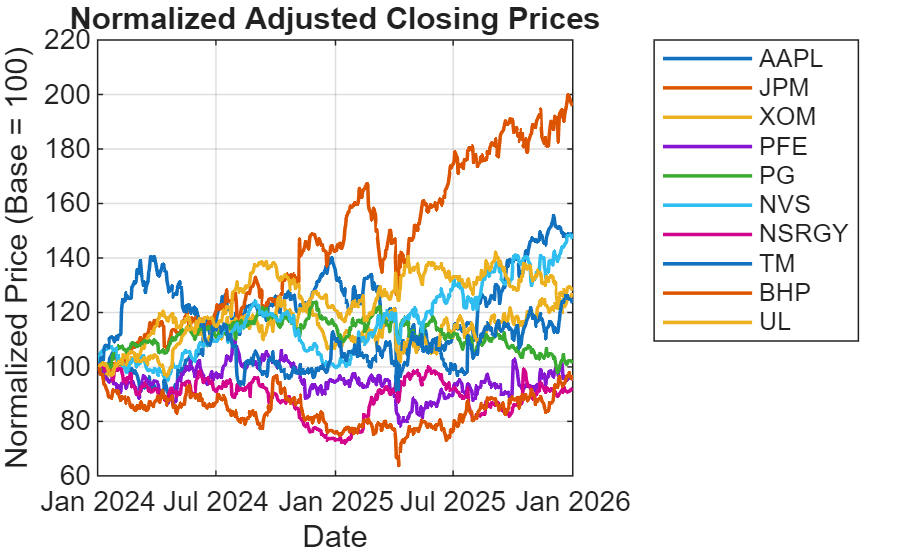

pricesNorm = 100 * prices ./ prices(1,:);

figure;
plot(dates, pricesNorm, 'LineWidth', 1.2);
grid on;

xlabel('Date');
ylabel('Normalized Price (Base = 100)');
title('Normalized Adjusted Closing Prices');

legend(symbols, 'Location', 'bestoutside');

A pronounced drawdown is visible around April across most assets, indicating a market-wide shock affecting all sectors simultaneously. This behaviour is consistent with a systematic risk event, likely driven by macroeconomic or financial market factors rather than firm-specific news. As expected, defensive stocks exhibit smaller drawdowns than cyclical and growth-oriented assets.

**Summary statistics (per asset)**

 % --- Summary statistics (per asset / column) ---


mu    = mean(rets, 1, 'omitnan')';     
sigma = std(rets, 0, 1, 'omitnan')';   
rmin  = min(rets, [], 1)';             
rmax  = max(rets, [], 1)';             
sk    = skewness(rets, 0, 1)';          
kt    = kurtosis(rets, 0, 1)';        

tickers = string(TTall.Properties.VariableNames(:));
% --- Annualization assumptions ---
tradingDays = 252;

% Annualized return for log returns: sum/additivity => mean * 252
annReturn = tradingDays * mu;

% Annualized volatility: sqrt(252) scaling
annVol = sqrt(tradingDays) * sigma;

% --- Build table ---
statsTbl = table(tickers, mu, sigma, annReturn, annVol, rmin, rmax, sk, kt, ...
    'VariableNames', {'Ticker','MeanDailyReturn','DailyVolatility', ...
                      'AnnReturn','AnnVol', ...
                      'MinDailyReturn','MaxDailyReturn','Skewness','Kurtosis'});

% --- Rank by volatility (ascending: least volatile first) ---
statsTbl = sortrows(statsTbl, 'DailyVolatility', 'ascend');
statsTbl.VolRank = (1:height(statsTbl))';
statsTbl = movevars(statsTbl, 'VolRank', 'After', 'Ticker');

% --- Automatic risk classification into Low/Medium/High ---
% Simple split into terciles by volatility rank
n = height(statsTbl);
riskClass = strings(n,1);
riskClass(1:ceil(n/3)) = "Low";
riskClass(ceil(n/3)+1:ceil(2*n/3)) = "Medium";
riskClass(ceil(2*n/3)+1:end) = "High";

statsTbl.RiskClass = riskClass;
statsTbl = movevars(statsTbl, 'RiskClass', 'After', 'VolRank');

% --- Display ---
disp(statsTbl);

    Ticker     VolRank    RiskClass    MeanDailyReturn    DailyVolatility    AnnReturn    AnnVol     MinDailyReturn    MaxDailyReturn    Skewness    Kurtosis
    _______    _______    _________    _______________    _______________    _________    _______    ______________    ______________    ________    ________

    "PG"          1       "Low"           8.4726e-05         0.010742         0.021351    0.17052      -0.050119           0.04139       -0.56411     5.9688 
    "UL"          2       "Low"           0.00056069         0.011539          0.14129    0.18317      -0.070276          0.059289       -0.14772     8

** Return distribution diagnostics**

Markowitz optimization and the Sharpe ratio summarize risk using only variance, which treats upside and downside deviations symmetrically and can understate tail risk. Heavy tails and negative skewness imply a greater probability of extreme losses than predicted by a normal model, making estimated Sharpe ratios and optimal weights less stable and potentially overly concentrated. For robustness, constraints and/or shrinkage can be used, and tail-risk measures (e.g., VaR/CVaR or downside semivariance) could be considered as extensions.

JB_p = zeros(numel(tickers),1);

for j = 1:numel(tickers)
    [~,JB_p(j)] = jbtest(rets(:,j));
end


JBtbl = table(tickers, JB_p, JB_p < 0.05, ...
    'VariableNames',{'Ticker','JB_pValue','RejectNormality'});

disp(JBtbl);

    Ticker     JB_pValue    RejectNormality
    _______    _________    _______________

    "AAPL"       0.001           true      
    "JPM"        0.001           true      
    "XOM"        0.001           true      
    "PFE"        0.001           true      
    "PG"         0.001           true      
    "NVS"        0.001           true      
    "NSRGY"      0.001           true      
    "TM"         0.001           true      
    "BHP"        0.001           true      
    "UL"         0.001           true      



**Correlation and dependence structure**

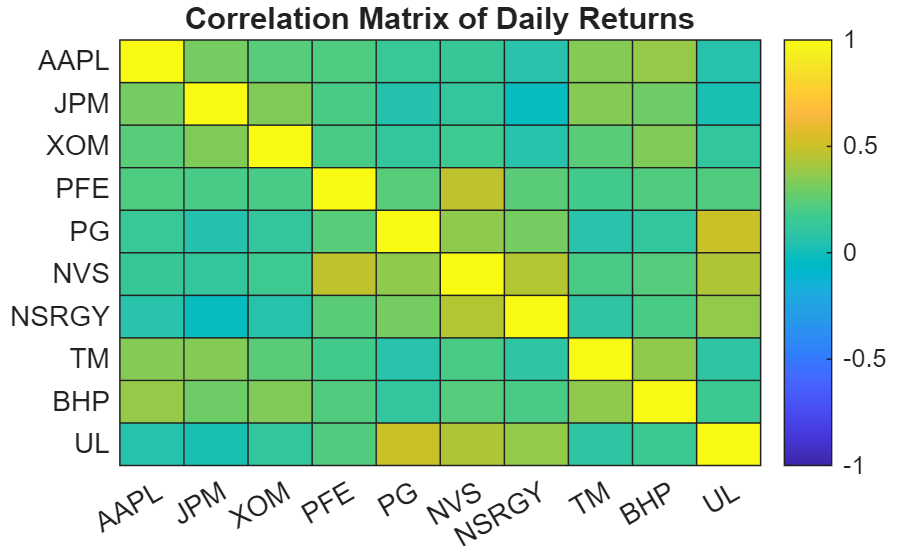

CorrMat = corr(rets, 'Rows','complete');   % N × N correlation matrix (Pearson)

figure;
heatmap(tickers, tickers, CorrMat, ...
    'Colormap', parula, ...
    'ColorLimits', [-1 1]);

title('Correlation Matrix of Daily Returns');




threshold = 0.8;   % high correlation threshold

[i,j] = find(triu(abs(CorrMat),1) > threshold);

highCorrPairs = table( ...
    tickers(i), tickers(j), CorrMat(sub2ind(size(CorrMat),i,j)), ...
    'VariableNames', {'Asset1','Asset2','Correlation'});

disp(highCorrPairs);

    Asset1    Asset2    Correlation
    ______    ______    ___________




The correlation structure highlights the limits of diversification within sectors and underscores the importance of cross-sector allocation in mean–variance portfolio construction.

No asset pairs exhibit correlations above the chosen high-correlation threshold. This indicates that the selected assets are not near-duplicates and that the portfolio benefits from meaningful cross-sector and cross-country diversification.

**Covariance matrix diagnostics (optimization stability)**

- Compute covariance matrix and check:

- positive semidefinite (PSD) issues (rare but possible)

- condition number / near-singularity (common with correlated assets)

CovMat = cov(rets, 'omitrows');   % N × N sample covariance matrix

eigVals = eig(CovMat);

minEig = min(eigVals);
fprintf("Minimum eigenvalue of covariance matrix: %.4e\n", minEig);

Minimum eigenvalue of covariance matrix: 5.8702e-05



if minEig < -1e-10
    warning("Covariance matrix is not positive semidefinite.");
end

condNumber = cond(CovMat);
fprintf("Condition number of covariance matrix: %.2e\n", condNumber);

Condition number of covariance matrix: 1.20e+01


Interpretation (rule of thumb):

- `cond < 1e3` → well-conditioned

- `1e3 – 1e5` → usable but sensitive

- `> 1e5` → **unstable**, near-singular

The estimated covariance matrix is positive semidefinite and well-conditioned, with a condition number on the order of 10¹. This indicates numerical stability in the mean–variance optimization and suggests that the resulting portfolio weights are not driven by near-singularity or estimation artefacts.

**Volatility stability over time (time variation)**

Risk is regime-dependent; estimates from calm periods understate risk during turbulent periods.

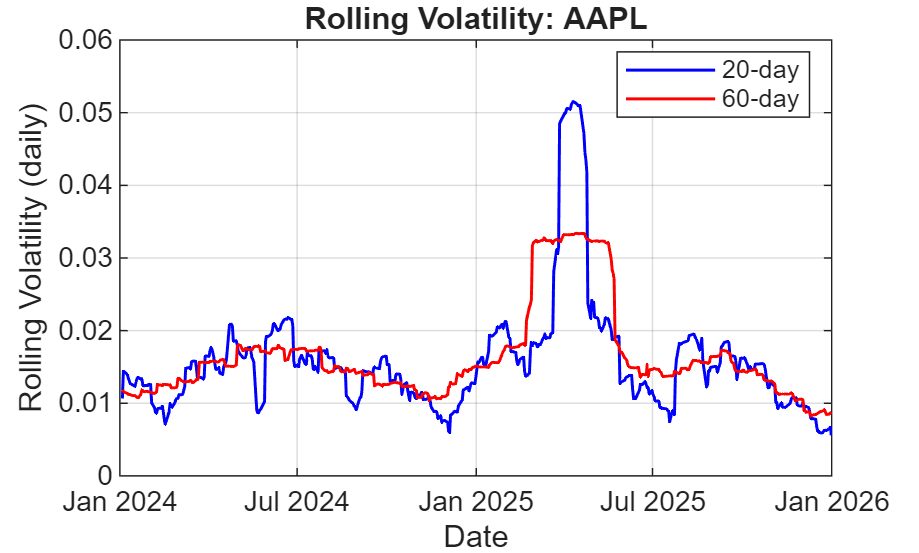

i = 1;   % index of asset to inspect
r = rets(:,i);
retDates = dates(2:end);   % returns start at t=2

%compute rolling volatility
win1 = 20;
win2 = 60;

rollVol20 = movstd(r, win1, 'omitnan');
rollVol60 = movstd(r, win2, 'omitnan');

figure;
plot(retDates, rollVol20, 'b', 'LineWidth', 1); hold on;
plot(retDates, rollVol60, 'r', 'LineWidth', 1);

grid on;
xlabel('Date');
ylabel('Rolling Volatility (daily)');
title("Rolling Volatility: " + tickers(i));
legend('20-day','60-day','Location','best');

The presence of time-varying volatility indicates that the constant-variance assumption underlying mean–variance optimization is an approximation. Risk estimates depend on the chosen sample window, and portfolios calibrated during calm periods may underestimate risk during turbulent regimes.

**Sensitivity to time window (quick robustness check)**

T = size(rets,1);
idxHalf = floor(T/2);

rets_full = rets;
rets_half = rets(idxHalf+1:end,:);


% Full sample
mu_full    = mean(rets_full,1)';
sigma_full = std(rets_full,0,1)';

% Last half
mu_half    = mean(rets_half,1)';
sigma_half = std(rets_half,0,1)';


Corr_full = corr(rets_full);
Corr_half = corr(rets_half);

avgCorr_full = mean(Corr_full(triu(true(size(Corr_full)),1)));
avgCorr_half = mean(Corr_half(triu(true(size(Corr_half)),1)));

fprintf("Average correlation (full sample): %.2f\n", avgCorr_full);

Average correlation (full sample): 0.22


fprintf("Average correlation (last half):   %.2f\n", avgCorr_half);

Average correlation (last half):   0.28


The increase in average correlation from 0.22 to 0.28 suggests that dependence strengthens during turbulent periods. While the covariance matrix remains well-conditioned, higher correlations reduce diversification benefits and contribute to greater sensitivity of mean–variance optimal portfolios.

## Create the portfolio object


p = Portfolio( ...
    'AssetList', symbols, ...
    'RiskFreeRate', rf)

p =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: 1.7869e-04
                     AssetMean: []
                    AssetCovar: []
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 10
                     AssetList: {'AAPL'  'JPM'  'XOM'  'PFE'  'PG'  'NVS'  'NSRGY'  'TM'  'BHP'  'UL'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: []
                    UpperBound: []
                   LowerBudget: []
                   UpperBudget: []
                   GroupMatrix: []
                





p = estimateAssetMoments(p, rets)

p =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: 1.7869e-04
                     AssetMean: [10×1 double]
                    AssetCovar: [10×10 double]
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 10
                     AssetList: {'AAPL'  'JPM'  'XOM'  'PFE'  'PG'  'NVS'  'NSRGY'  'TM'  'BHP'  'UL'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: []
                    UpperBound: []
                   LowerBudget: []
                   UpperBudget: []
                   GroupMatr

Use the default for a  long fully-invested portfolio by chosing the default constraints

p = setDefaultConstraints(p)

p =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: 1.7869e-04
                     AssetMean: [10×1 double]
                    AssetCovar: [10×10 double]
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 10
                     AssetList: {'AAPL'  'JPM'  'XOM'  'PFE'  'PG'  'NVS'  'NSRGY'  'TM'  'BHP'  'UL'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: [10×1 double]
                    UpperBound: []
                   LowerBudget: 1
                   UpperBudget: 1
                   

# Portfolio Performance Evaluation

#### Evaluating  performance based on average return alone is not very useful. Returns must be adjusted for risk before they can be compared meaningfully. 

#### Methods of risk-adjusted performance evaluation  using mean-variance criteria came on stage simultaneously with the capital asset pricing model. 

#### One popular measure is the Sharpe Ratio:

#### 
$$SR = \frac{\mathbb E[R_P]-R_f}{\sigma_P}$$


#### that divides average portfolio excess return over the sample period by the standard deviation of returns over that period. 

#### It measures the reward to (total) volatility trade-off. With mean-variance preferences, one wants to maximize the Sharpe ratio. 

#### Note that other risk-adjusted performance measures for a portfolio are:

#### Treynor measure:

####  $\frac{\mathbb E[R_P]-R_f}{\beta_P}$. 

#### Like Sharpe's, it gives excess return per unit of risk, but using systematic risk instead of total risk.

#### Jensen measure (portfolio alpha)

####  
$$\alpha_P = \mathbb E[R_P] - \mathbb E[R_M] +\beta_P(\mathbb E[R_M]-r_f)$$


#### Jensen's measure is the average return on the portfolio over and above that predicted by the CAPM, given the portfolio's beta and  the average market return. Jensen's measure is the portfolio's alpha value.

#### Information ratio:

#### 
$$\frac{\alpha_P }{\sigma(e_P)}$$


#### It divides the alpha of the portfolio by the nonsystematic risk of the portfolio, also called 'tracking error' in the industry. 

#### It measures abnormal returns per unit of risk that in principle could be diversified away by building a market index portfolio.

#### We want now to estimate the portfolio that is maximizing the Sharpe Ratio


w1 = estimateMaxSharpeRatio(p)

w1 =     0.0771
    0.4918
    0.0000
    0.0000
    0.0000
    0.3057
    0.0000
    0.0000
    0.0000
    0.1254


Portfolio weights are converted into monetary allocations by multiplying by the total investment budget of £150,000. 


budget = 150000;              % total budget in GBP
allocation = budget * w1;     % GBP allocation implied by portfolio weights

The number of shares is not computed, as the focus is on relative allocation rather than trade execution.


% ===== Optimal portfolio (daily moments) =====
[risk1, ret1] = estimatePortMoments(p, w1);

% Annualize portfolio moments
ret1_ann  = ret1  * 252;
risk1_ann = risk1 * sqrt(252);

% Annualized Sharpe ratio (consistent with rf)
Sharpe_p = (ret1 - rf) / risk1 * sqrt(252);


% ===== S&P 500 (daily moments) =====
ret_SP  = mean(SP_rets, 'omitnan');
risk_SP = std(SP_rets,  'omitnan');

% Annualize S&P 500 moments
ret_SP_ann  = ret_SP  * 252;
risk_SP_ann = risk_SP * sqrt(252);

% Annualized Sharpe ratio
Sharpe_SP = (ret_SP - rf) / risk_SP * sqrt(252);


% ===== Comparison table (ALL annualized) =====
CompTbl = table( ...
    ["Optimal Portfolio"; "S&P 500"], ...
    [ret1_ann;  ret_SP_ann], ...
    [risk1_ann; risk_SP_ann], ...
    [Sharpe_p;  Sharpe_SP], ...
    'VariableNames', {'Asset','AnnualizedReturn','AnnualizedVolatility','AnnualizedSharpe'});

disp(CompTbl);

           Asset           AnnualizedReturn    AnnualizedVolatility    AnnualizedSharpe
    ___________________    ________________    ____________________    ________________

    "Optimal Portfolio"        0.28141               0.15364                1.5385     
    "S&P 500"                  0.18458               0.15922               0.87642     



The improvement in risk-adjusted performance is consistent with the moderate correlation structure, good covariance conditioning, and diversification benefits identified in the diagnostic analysis.

However, the superior Sharpe ratio of the optimized portfolio should be interpreted with caution, as mean–variance optimization is performed in-sample and is sensitive to estimation error.

## **Data Visualization: plot the efficient frontier and risk and returns of assets**

Plot the risk and returns of the assets

[m, cov] = getAssetMoments(p);

scatter(sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.

xlabel('Risk')

ylabel('Expected Return')

text(sqrt(diag(cov))+0.0003,m,symbols,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier in the same graphical window`

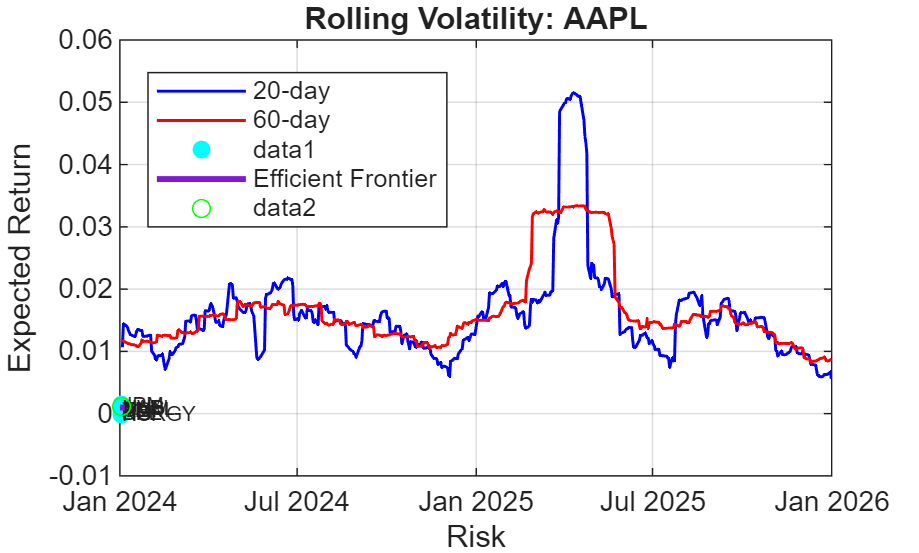

hold on;

[risk2, ret2]  = plotFrontier(p);


plot(risk1,ret1,'og');

hold off

The figure illustrates the gross (pre-cost) risk–return opportunity set implied by the data; net realized performance would depend on implementation costs, but the relative positioning of assets and the diversification benefits remain informative.

Extrapolate portolios' weights

pwgt = estimateFrontier(p)

pwgt =     0.0487    0.0615    0.0722    0.0828    0.0908    0.0897    0.0726    0.0428         0         0
    0.1317    0.1660    0.2057    0.2458    0.2951    0.3990    0.5161    0.6474    0.8268    1.0000
    0.1534    0.1477    0.1340    0.1197    0.0960    0.0208         0         0         0         0
    0.0313    0.0026         0         0         0         0         0         0         0         0
    0.2416    0.2017    0.1465    0.0901    0.0075         0         0         0         0         0
    0.0668    0.1171    0.1641    0.2105    0.2500    0.2839    0.3106    0.3098    0.1732         0
    0.1220    0.0946    0.0543    0.0132         0         0         0         0         0         0
    0.0347    0.0268    0.0139    0.0008         0         0         0         0         0         0
    0.0094         0         0         0         0         0         0         0         0         0
    0.1604    0.1820    0.2093    0.2371    0.2606    0.2066    0.1007         0    

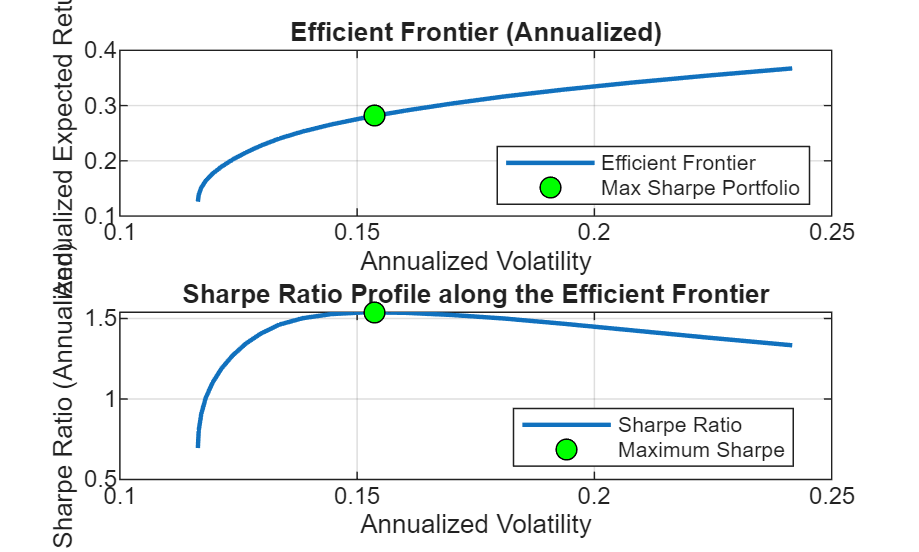

% Number of frontier portfolios
nPorts = 20;

% Efficient frontier
W = estimateFrontier(p, nPorts);                 % N × nPorts
[riskF, retF] = estimatePortMoments(p, W);       % daily moments

% Tangency (max Sharpe) portfolio
w_tan = estimateMaxSharpeRatio(p);
[riskT, retT] = estimatePortMoments(p, w_tan);   % daily moments

% ---- Annualize ----
retF_ann  = retF  * 252;
riskF_ann = riskF * sqrt(252);

retT_ann  = retT  * 252;
riskT_ann = riskT * sqrt(252);

% Sharpe profile (annualized Sharpe)
SharpeF = ((retF - rf) ./ riskF) * sqrt(252);
SharpeT = ((retT - rf) /  riskT) * sqrt(252);

% ---- Plot ----
figure;

% (Top) Efficient frontier
subplot(2,1,1);
plot(riskF_ann, retF_ann, 'LineWidth', 1.5); hold on;
plot(riskT_ann, retT_ann, 'ko', 'MarkerFaceColor','g', 'MarkerSize',7);
grid on;
xlabel('Annualized Volatility');
ylabel('Annualized Expected Return');
title('Efficient Frontier (Annualized)');
legend('Efficient Frontier','Max Sharpe Portfolio','Location','best');

% (Bottom) Sharpe ratio profile
subplot(2,1,2);
plot(riskF_ann, SharpeF, 'LineWidth', 1.5); hold on;
plot(riskT_ann, SharpeT, 'ko', 'MarkerFaceColor','g', 'MarkerSize',7);
grid on;
xlabel('Annualized Volatility');
ylabel('Sharpe Ratio (Annualized)');
title('Sharpe Ratio Profile along the Efficient Frontier');
legend('Sharpe Ratio','Maximum Sharpe','Location','best');

The top panel reports the annualized efficient frontier under long-only, fully invested constraints, with the tangency portfolio highlighted. The bottom panel shows the Sharpe ratio profile as a function of portfolio risk along the frontier. The optimal portfolio coincides with the maximum of the Sharpe ratio profile, confirming that it maximizes risk-adjusted performance relative to the chosen risk-free rate.

# Limitations of the mean-variance approach

#### The portfolio optimization technique we have used so far assume normal distributions of returns in that standard deviation is taken to be a fully adequate measure of risk. 

#### However, potential nonnormality of returns requires us to pay attention as well to risk measures that focus on worst-case losses such as value at risk (VaR) or expected shortfall (ES).

#### Capital allocation to the risky portfolio should be reconsidered in the face of fat-tailed distributions that can result in extreme values of VaR and ES. 

#### Specifically, forecasts of greater VaR and ES should encourage more moderate portfolio allocations to the risky portfolio. When we select the composition of the optimal risky portfolio itself, considering the effect of diversification cannot be readily simplified in this case as we are able to do when returns are normally distributed.

#### Another limitation of the mean-variance approach  arises from the fact that the covariance matrix is assumed to be constant over time. Unfortunately, it is likely that correlation may rise when stock market crashes occur, just when diversification should help. 

#### So, we might use more complex models in describing uncertainty if required. 

#### This also enables us to consider another feature that is disregarded by mean-variance portfolios: the dynamic nature of portfolio management, which is not considered in single-period models. Portfolios are revised in time, and the impact of transaction costs should not be neglected.

#### It might be also advisable to avoid a portfolio with a very small weight on some assets; the benefit of diversification will probably be lost because of increasing transaction costs. So, we could require that if a stock enters the portfolio, it does with a minimal weight. We may also look for portfolios including no more than a predetermined number of assets.

#### Some of these features need to be included as constraints in our optimization procedure.

#### Markowitz published in 1952 ('Portfolio Selection', Journal of Finance) a formal model of portfolio selection embodying diversification principles, thereby paving the way for his 1990 Nobel Prize in Economics. 

#### His model is step one of portfolio management: the identification of the efficient set of portfolios, or the efficient frontier of risky assets. 

#### The portfolios we discuss of are of a short-term horizon, even if the overall ivestment horizon is long, portfolio composition can be rebalanced. 

#### For these short-horizons, the skewness that characterizes long-term compounded returns might be negligible. Therefore, the assumption of normality can be sufficiently accurate, under some conditions, to describe holding-period returns, and we will be concerned only with portfolio means and variances.

#### The idea is that, for any risky level, we are interested only in that portfolio with the highest expected return. 

#### Alternatively, the frontier is the set of portfolios that minimizes the variance for any target expected return. 

#### Let's enter more details. 

#### Portfolio weights:

#### 
$$w_i (0)=\frac{S_i(0)\,x_i}{V(0)}\qquad i=1,\dots,n$$


#### $x_i$  # shares of type $i$ in the portfolio

#### $S_i(0)$ initial price of security $i$

#### $V(0)$ amount initially invested in the portfolio

#### Consider first the asset allocation problem when only two risky assets are available.

#### Let's denote: 

#### $\bar R_i$ expected rate of return for the i-th asset

#### $\sigma_i$ standard deviation rate of return for the i-th asset

#### It is tempting to say that the problem is trivial when $\bar R_1>\bar R_2$ and $\sigma_1<\sigma_2$. A naive argument may led to conclude that the second asset might not be considered at all; actually it is instead beneficial in reducing risk, if it is negatively correlated with the return of the first asset.

#### We need to formalize the problem and solve it by using a constrained optimization procedure.

#### The expected portfolio return is

#### 
$$\bar R_P= w_1\bar R_1+w_2\bar R_2$$
 

#### More generally, when considering a portfolio of n risky assets,

#### 
$$\bar R_P= \sum_{i=1}^nw_i\bar R_i = \mathbf w' \bar{\mathbf R$$


#### with $\mathbf w = \left (\begin{array} {c}w_1\\w_2\\ \dots\\w_n\end{array}\right)$ 

#### and 

#### $\bar{\mathbf R} = \left (\begin{array} {c}\bar R_1\\\bar R_2\\ \dots\\\bar R_n\end{array}\right)$ .

#### The compounding frequency defines the units in which an interest rate is measured.

#### A variable's volatility, $\sigma$, is defined as the standard deviation of the return provided by the variable per unit of time when the return is expressed using continuous compounding. Usually, when volatility is used for option pricing, the unit of time is one year, so that volatility is the standard deviation of the continuously compounded return per year. 

#### When volatility is used for risk management, the unit of time is usually one day so that volatility is the standard deviation of the continuously compounded return per day.

#### The cc return per day of a variable whose value is $S_i$ at the end of day i, is

#### 
$$ln\frac{S_i}{S_{i-1}}$$


#### that is almost the same as (over a short investment horizon)

#### 
$$\frac{S_i}{S_{i-1}}$$


#### Then, the usual definition of volatility in risk management, is the standard deviation of the proportional change in the variable during a day.

#### Risk managers often focus on the variance rate rather than the volatility. 

#### The variance rate is defined as the square of the volatility. The variance rate per day is the variance of the return in one day.

#### If we assume that the returns each day are independent with the same variance, the variance of the return over T days is T times the variance of the return over one day.This means that the standard deviation of the return over T days is $\sqrt T$ times the standard deviation of the return over one day.

####  "Uncertainty increases with the square root of time".

#### Then, the variance increases linearly with time.

#### Research shows that volatility is much higher on business days than on non-business days. As a result, analysts tend to ignore weekends and holidays when calculating and using volatilities. 

#### The usual assumption is that there are 252 days per year.

#### Assuming that the returns on successive days are independent and have the same standard deviation, this means that

#### 
$$\sigma_{yr}=\sigma_{day}\sqrt{ 252}$$


####  showing that daily volatility is about 6% of annual volatility.

#### A note on normally distributed returns

#### Suppose that an asset price is £60 and that its daily volatility is 2%. This means that a one-standard-deviation move in the asset price over one day would be $60\times 0.02=1.20$. 

#### If we assume that the change in the asset price is normally distributed, we can be 95% certain that the asset price will be between $60-1.96\times1.2=\textsterling 57.65$and  $60+1.96\times1.2=\textsterling 62.35$ at the end of the day.

#### Portfolio risk 

#### The variance of the random portfolio rate of return for the special case of two risky assets is given by

#### 
$$\sigma^2=Var(w_1R_1+w_2R_2)=w_1^2\sigma_1^2+w_2^2\sigma_2^2+2w_1w_2\sigma_{12}$$


#### where $\sigma_{12}$ is the covariance between the retuns of the two assets.

#### For n assets we have

#### 
$$\sigma^2=\sum_{i,j=1}^nw_iw_j\sigma_{ij} =\mathbf w'\mathbb \Sigma\mathbf w$$


#### where all covariances have been collected into$\sigma_{ij}$, i.e. the covariance matrix $\mathbb \Sigma$.

#### By choosing the weights $w_i$, we will get different portfolios each of them characterized by its expected value of return and by its variance or standard deviation, which we may assume as a risk measure. 

#### Any investor would like  to maximize the expected return and to minimize variance. 

#### Since these two objectives are, in general, conflicting, we must find a trade-off. 

#### This trade-off will depend on the degree of risk aversion (hard to assess), but it is reasonable to assume that for a given target value of the portfolio expected retuns$\bar R_T$ , one would like to minimize variance. 

#### As a result, the optimization problem can formalized as

#### 
$$min\quad \mathbf w'\mathbb \Sigma\mathbf w\\
s.t.\quad \mathbf w'\bar\mathbf R={\bar R}_T\\
with\:\sum_{i=1}^n w_i=1\\
$$


#### Constraints for a  long-only fully  invested portfolio:

#### $\mathbf w'\cdot \mathbb l=1$(in matrix notation)             (fully)

#### with $w_i\geq 0\qquad i=1,\dots,n$              (long)

#### Summarizing, portfolios of less than perfectly correlated assets always offer better risk-return opportunities that the individual securities on their own. The lower the correlation between the assets, the greater the gain in efficiency. 

#### The minimum-variance portfolio has a standard deviation smaller than that of either of the individual component assets.

#### The expected return and variance of any risky portfolio with weights in each security, $w_i\geq 1\quad i=1,\dots,n$  can be calculated by applying the optimization procedure.

#### By changing the target expected return, one may obtain a set of efficient portfolios. 

#### Roughly speaking, a portfolio is efficient if it is not possible to obtain a higher expected return without increasing risk.



function TT = getYahooDaily(symbol, startDate, endDate)
% Download daily Adjusted Close from Yahoo Finance chart API.
% Robust to missing adjclose and inclusive end-date.

% Ensure datetimes
startDate = datetime(startDate,'TimeZone','UTC');
endDate   = datetime(endDate,'TimeZone','UTC');

% Yahoo period2 is effectively exclusive, so push it forward by 1 day
p1 = floor(posixtime(startDate));
p2 = floor(posixtime(endDate + days(1)));

url = "https://query1.finance.yahoo.com/v8/finance/chart/" + symbol + ...
      "?period1=" + p1 + "&period2=" + p2 + ...
      "&interval=1d&events=history&includeAdjustedClose=true";

opts = weboptions( ...
    'Timeout',30, ...
    'UserAgent','Mozilla/5.0 (Windows NT 10.0; Win64; x64)', ...
    'ContentType','json');

raw = [];
for k = 1:3
    try
        raw = webread(url,opts);
        break
    catch ME
        pause(2 + rand)
        if k == 3
            error("Yahoo Finance request failed for %s: %s", symbol, ME.message);
        end
    end
end

% Basic validation
if isempty(raw) || ~isfield(raw,"chart") || isempty(raw.chart.result)
    error("No data returned for %s.", symbol);
end

r = raw.chart.result;
t = r.timestamp;

% Prefer adjusted close; fallback to close
adj = [];
if isfield(r,"indicators") && isfield(r.indicators,"adjclose") && ~isempty(r.indicators.adjclose)
    adj = r.indicators.adjclose.adjclose;
end

if isempty(adj) || all(isnan(adj))
    if isfield(r.indicators,"quote") && ~isempty(r.indicators.quote)
        adj = r.indicators.quote.close;
        warning("AdjClose missing for %s. Falling back to Close.", symbol);
    else
        error("No usable price series for %s.", symbol);
    end
end

Date = datetime(t,'ConvertFrom','posixtime','TimeZone','UTC');
AdjClose = adj(:);

TT = timetable(Date(:),AdjClose,'VariableNames',"AdjClose");
TT = rmmissing(TT);
TT = sortrows(TT);
end


